clear all
clf

%The following path has to be adjusted for each computer!!!!!
source_dir = 'D:/A_Karos Kram/Studium England/Year2/MAPS2001/1project/MATLAB-Isotopes-master/MATLAB-Isotopes-master/MakingMaps/';

source_dir = 'D:/A_Karos Kram/Studium England/Year2/MAPS2001/1project/MATLAB-Isotopes-master/MATLAB-Isotopes-master/MakingMaps/'


%Load all .xls files (the climate data) into one cell array
AATdata=loadfiles(source_dir,'*.xls');

%Load all .xlsx files (the Isotope data) into one cell array
Isotopedata=loadfiles(source_dir,'*xlsx');


%Calculate the means and medians for H2, H3, O18 and Temperature across all datasets
means=zeros(size(Isotopedata,1),4); %creates arrays full of zeros of the right size
medians=zeros(size(Isotopedata,1),4);

for i= 1:length(Isotopedata)
    
   activedata=Isotopedata{i,1};                    
   tempdata=AATdata{i,1};
   
   means(i,1)=mean(activedata.H2, 'omitnan');       %Means for the isotopes
   means(i,2)=mean(activedata.H3, 'omitnan');
   means(i,3)=mean(activedata.O18, 'omitnan');
                                                
   medians(i,1)=median(activedata.H2, 'omitnan');   %Medians for the isotopes
   medians(i,2)=median(activedata.H3, 'omitnan');
   medians(i,3)=median(activedata.O18, 'omitnan');
                    
   means(i,4)=mean(tempdata.tas, 'omitnan');        %Means for temperatures
    
   medians(i,4)=median(tempdata.tas, 'omitnan');    %Medians for temperatures
   
end  


According to the  reference *G. Torri, D. Ma, Z. Kuang Stable water isotopes and large-scale vertical motions in the tropics, Journal of Geophysical Research: Atmospheres Volume 122, Issue 7, pages 3703-3717, 2017 *on page 3707, the abundance of deuterium is measured with the following formula:


$$\delta D=\left(\frac{R_{\mathrm{sample}} }{R_{\mathrm{VSMOW}} }-1\right)\cdot 1000\text{ }‰$$


where:

$R_{\mathrm{sample}}$ is the ratio of deuterium to the common, stable isotope of hydrogen in the samples considered,

 $R_{\mathrm{VSMOW}}$ is the same ratio but for a reference sample with the isotopic composition of the Vienna standard mean ocean water.


$$R_{\text{VSMOW}} =155\ldotp 76\pm 0\ldotp 1ppm$$
 


% The H3 abundance is not given in Delta D, but in TU (Tritium atoms per 1018 Hydrogen atoms), so Delta D must be calculated:
vsmow=1.85*10^-11;   %Given in ppm 
means(:,2)=((means(:,2).*(1/1018)./vsmow)-1).*1000

means =    1.0e+13 *

   -0.0000    1.4455   -0.0000    0.0000
   -0.0000    0.1527   -0.0000    0.0000
   -0.0000    0.1274   -0.0000    0.0000
   -0.0000    0.0488   -0.0000    0.0000
   -0.0000    0.1019   -0.0000    0.0000
   -0.0000    0.8573   -0.0000    0.0000
    0.0000    0.5464    0.0000    0.0000
   -0.0000    0.0215   -0.0000    0.0000
   -0.0000    0.0637   -0.0000    0.0000
   -0.0000    0.2045   -0.0000    0.0000


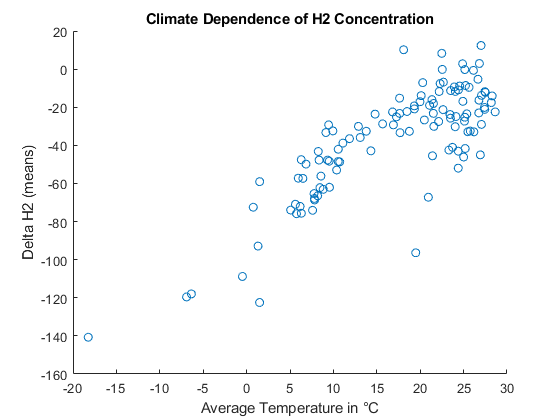

medians(:,2)=((medians(:,2).*(1/1018)./vsmow)-1).*1000;


%Plot scatterplots of isotope concentration in precipitation vs temperature

scatter(means(:,4),means(:,1));     %H2 mean values
xlabel('Average Temperature in °C');
ylabel('Delta H2 (means)');
title('Climate Dependence of H2 Concentration');

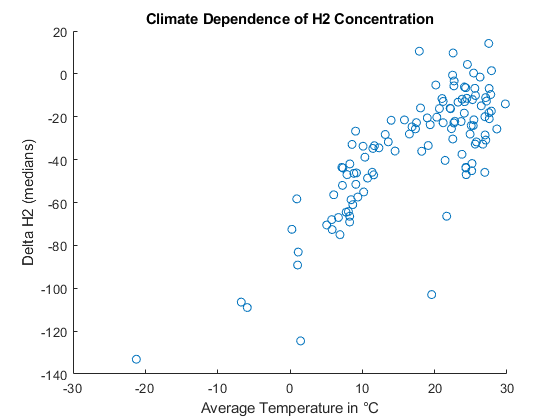


scatter(medians(:,4),medians(:,1));     %H2 median values
xlabel('Average Temperature in °C');
ylabel('Delta H2 (medians)');
title('Climate Dependence of H2 Concentration');

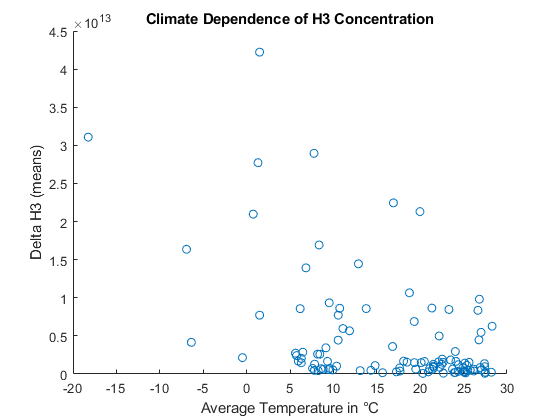


scatter(means(:,4),means(:,2));     %H3 mean values
xlabel('Average Temperature in °C');
ylabel('Delta H3 (means)');
title('Climate Dependence of H3 Concentration');

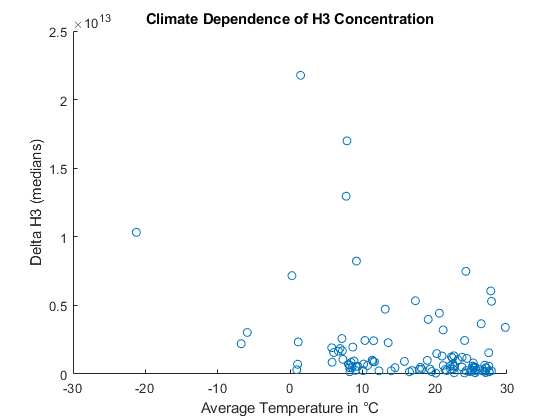


scatter(medians(:,4),medians(:,2));     %H3 median values
xlabel('Average Temperature in °C');
ylabel('Delta H3 (medians)');
title('Climate Dependence of H3 Concentration');

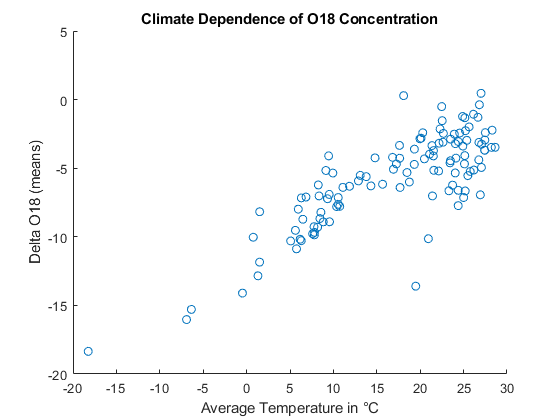


scatter(means(:,4),means(:,3));     %O18 mean values
xlabel('Average Temperature in °C');
ylabel('Delta O18 (means)');
title('Climate Dependence of O18 Concentration');

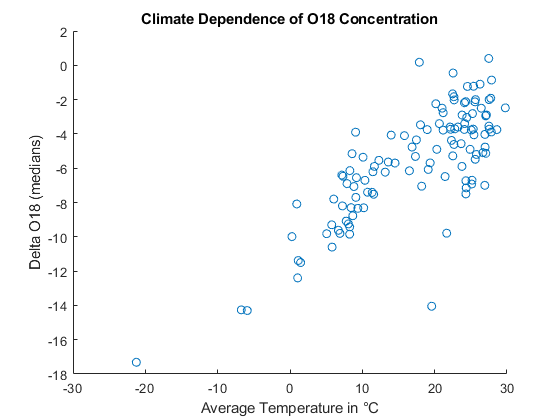


scatter(medians(:,4),medians(:,3));     %O18 median values
xlabel('Average Temperature in °C');
ylabel('Delta O18 (medians)');
title('Climate Dependence of O18 Concentration');

Quantify this relation for t < 15° for Deuterium and O18

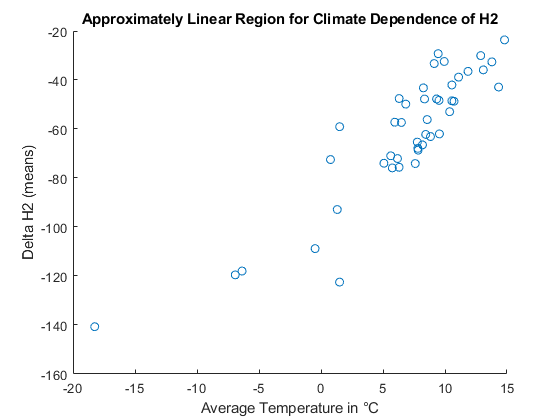

%First, collect all mean and median values for temperatures below 15°C only
m=1;
n=1;
for k=1:length(means)
    if means(k,4)<15
        behavedmeans(m,:)=means(k,:);        %Means that theoretically follow the relationship
        m=m+1;
    end
    if medians(k,4)<15
        behavedmedians(n,:)=medians(k,:);    %Medians that theoretically follow the relationship
        n=n+1;
    end
end

%Plot these relevant regions
scatter(behavedmeans(:,4),behavedmeans(:,1));
xlabel('Average Temperature in °C');
ylabel('Delta H2 (means)');
title('Approximately Linear Region for Climate Dependence of H2');

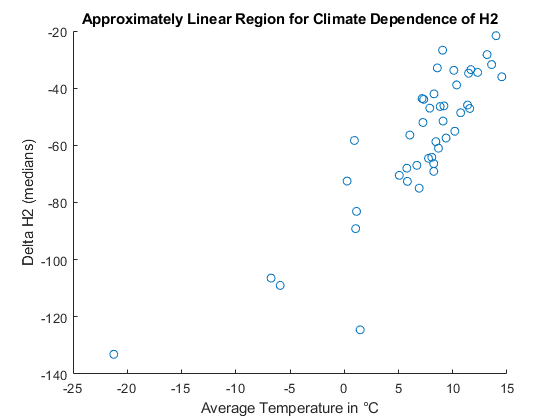


scatter(behavedmedians(:,4),behavedmedians(:,1));
xlabel('Average Temperature in °C');
ylabel('Delta H2 (medians)');
title('Approximately Linear Region for Climate Dependence of H2');

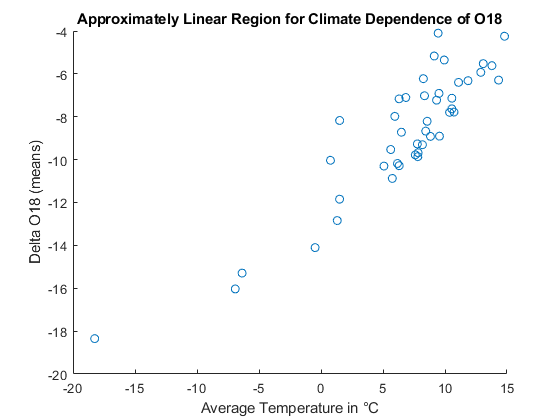


scatter(behavedmeans(:,4),behavedmeans(:,3));
xlabel('Average Temperature in °C');
ylabel('Delta O18 (means)');
title('Approximately Linear Region for Climate Dependence of O18');

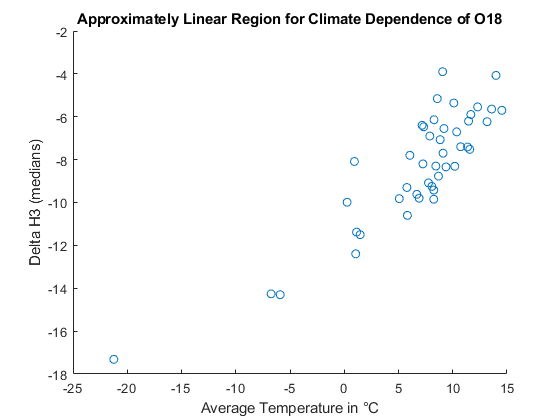


scatter(behavedmedians(:,4),behavedmedians(:,3));
xlabel('Average Temperature in °C');
ylabel('Delta H3 (medians)');
title('Approximately Linear Region for Climate Dependence of O18');

Next we want to find out whether means or medians provide the better linear regression and which Isotope most closely  abides a linear relationship. We use a function which inputs minimum two arrays of equal size and calculates a line of best fit for the first array against all the others in turn.

H2Fit=fitfunction(means(:,4),means(:,1),medians(:,1))

H2Fit = 1×3 cell array
    {1×1 cfit}    {[0.6291]}    {[2]}


O18Fit=fitfunction(means(:,4),means(:,3),medians(:,3))

O18Fit = 1×3 cell array
    {1×1 cfit}    {[0.6279]}    {[2]}


BestFit=fitfunction(means(:,4),means(:,1),medians(:,1),means(:,3),medians(:,3))

BestFit = 1×3 cell array
    {1×1 cfit}    {[0.6279]}    {[4]}


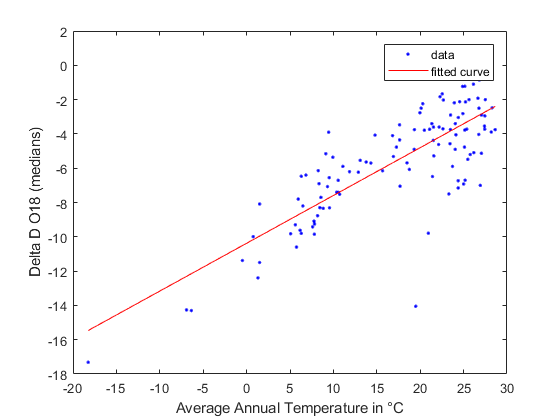


plot(BestFit{1},means(:,4), medians(:,3));
xlabel('Average Annual Temperature in °C');
ylabel('Delta D O18 (medians)');


BestFit{1}

ans =      Linear model Poly1:
     ans(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =      0.2787  (0.2391, 0.3183)
       p2 =      -10.38  (-11.14, -9.61)

Functions used in this script. They could be moved to an external file.

function bestfit=fitfunction(X,varargin)    %FitFunction accepts a variable number of input argument

    fits=cell(length(varargin),1);
    gof=zeros(length(fits),1);
    
    for i=1:length(varargin)
        [~, gofi]=fit(X,varargin{i},'poly1');
        gof(i)=gofi.rsquare;
    end
    
    [bestgof, gofnb]=min(gof);
    coefficients=fit(X,varargin{gofnb},'poly1');
    
    bestfit={coefficients,bestgof,gofnb};
end

function loadedfiles=loadfiles(filepath, filextension)

source_files = dir(fullfile(filepath, filextension));
loadedfiles=cell(size(source_files));

    for i = 1:length(source_files)
      loadedfiles{i} = readtable(fullfile(filepath, source_files(i).name));  
    end

end





